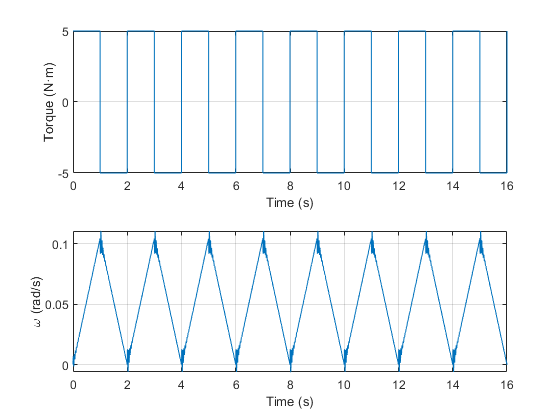

%% add Task2
% Исходные данные: файл, содержащий записи момента и скорости первой 
% массы с периодом дискретизации 1 мс и значение коэффициента жесткости 
% K12.
% Задания: 
% а) определить параметры двухмассовой механической системы; 
% б) собрать модель с идентифицированными параметрами; 
% в) промоделировать с входным воздействием из исходного файла; 
% г) посчитать среднеквадратичную ошибку между скоростью первой массы с 
% модели и скоростью первой массы из исходного файла
u = sim_res.out_var.signals.values(:,1);
w1 = sim_res.out_var.signals.values(:,2);
t = sim_res.out_var.time;

figure;
ax1 = subplot(2,1,1);
plot(t, u)
grid on
xlabel("Time (s)"), ylabel("Torque (N·m)")
ax2 = subplot(2,1,2);
plot(t, w1)
grid on
xlabel("Time (s)"), ylabel("\omega (rad/s)")
linkaxes([ax1,ax2],'x')

%%
% w1_osc = detrend(w1, 1, u == -5);

figure;
ax1 = subplot(2,1,1);
plot(t, u)
grid on
xlabel("Time (s)"), ylabel("Torque (N·m)")
ax2 = subplot(2,1,2);
plot(t, w1_osc)
grid on
xlabel("Time (s)"), ylabel("\omega (rad/s)")
linkaxes([ax1,ax2],'x')
%%
Kw = 0.104558/1/5

Kw = 0.0209


T2=(2.049-2.009)/(2*pi)

T2 = 0.0064

ksi2=-log(0.00679353/0.0114221)/(2*pi)

ksi2 = 0.0827

%%
B12 = ksi2*T2*2*K12

B12 = 105.2888


syms x;
J_roots = solve(Kw*x^2 - x + T2^2*K12 == 0, x);
double(J_roots)

ans =     4.4708
   43.3495


J2 = double(J_roots(2))

J2 = 43.3495

T1=sqrt(J2/K12)

T1 = 0.0208

ksi1=B12/(2*K12*T1)

ksi1 = 0.0253


J1=1/Kw-J2

J1 = 4.4708

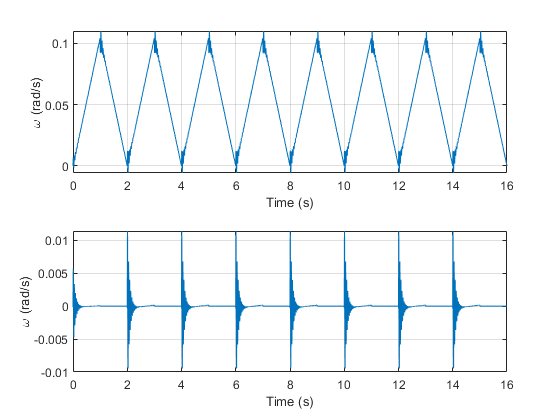

%% E_DriveLab1AddTask2 modeling
simtime = 16;
res = sim('E_DriveLab1AddTask.slx', simtime);
%%
u_counted = res.out.signals.values(:,1);
w1_counted = res.out.signals.values(:,2);
t_counted = res.out.time;
%%
ax1 = subplot(2,1,1);
plot(t, w1_counted)
grid on
xlabel("Time (s)"), ylabel("\omega (rad/s)")


%%
e_mse = mse(w1, w1_counted)

e_mse = 5.7134e-08